

clear all;
close all;
clc

% parametry
t0 = 0;
tk=10;
omega=1;

f1=@(x) x;
f2=@(x) -omega^2*sin(x);

leg=[];
figure()
hold on
H=logspace(0,-3,9);
for h=H
    
    Y=[];
    % warunki poczatkowe
    Y(1,1)=pi/2;
    Y(1,2)=0;
    t=t0:h:tk;
    for i=1:length(t)-1
        y1 = Y(i,1)+h*f1(Y(i,2));
        y2 = Y(i,2)+h*f2(Y(i,1));
        Y=[Y; [y1, y2]];
    end
    plot(t,Y(:,1),'x')
    
    %leg=[leg num2str(h)]
    leg=[leg ; h];
end
leg=num2str(leg(1:length(H)),2)
legend(leg)
title(['Stabilność metody otwartej Eulera dla układu równań (wahadło)' newline 'w zależności od długości kroku h'])
xlabel('t')

leg = 6×6 char array
    '     1'
    ' 0.422'
    ' 0.178'
    ' 0.075'
    '0.0316'
    '0.0133'


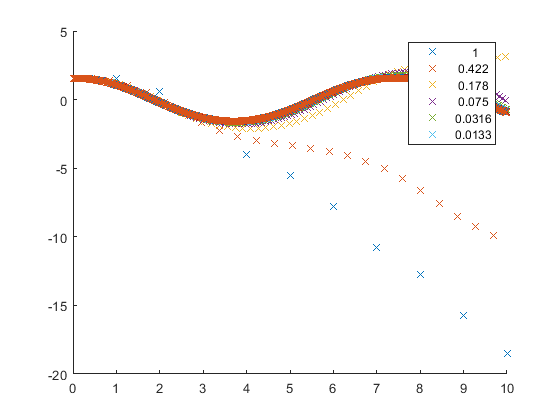

ylabel('Y_1(t)')
hold off